## Load data

warning off;
addpath('./hyper_params');
prefix = 'us'; % Can be changed to 'global'
eval(['load_data_' prefix]);


## Data smoothing

data_4_s = [data_4(:, 1) cumsum(movmean(diff(data_4')', 7, 2), 2)];
deaths_s = deaths;


## Load Reported Cases Hyperparameters

hyper_day = 134;
eval(['load '  prefix '_hyperparam_ref_' num2str(hyper_day)]);
best_param_list = best_param_list_no;
MAPEtable_s = MAPEtable_notravel_fixed_s;


## Set hyperparameters here (may replace by grid-search for hyperparameters)

dk = 3;
djp = 7;
alpha = 0.8;


## Load hyperparameters for reference day (social distancing)

reference_day = 64;
eval(['load '  prefix '_hyperparam_ref_' num2str(reference_day)]);


## Perform death predictions and write files for various factors of unreported cases

T_full = size(data_4, 2);
un_array = [1, 2, 5, 10, 20, 40]; % Select the ratio of total to reported cases
horizon = 100; % days of reported cases predcitions
dhorizon = horizon; % days of deaths predcitions

for un_id = 1:length(un_array)
    % Train with hyperparams before and after
    un = un_array(un_id); % Select the ratio of true cases to reported cases. 1 for default.
    
    beta_notravel = var_ind_beta_un(data_4_s(:, 1:reference_day), passengerFlow*0, best_param_list_no(:, 3)*0.1, best_param_list_no(:, 1), un, popu, best_param_list_no(:, 2));
    beta_after = var_ind_beta_un(data_4_s(:, 1:T_full), passengerFlow*0, best_param_list(:, 3)*0.1, best_param_list(:, 1), un, popu, best_param_list(:, 2));
        
    alpha_l = MAPEtable_notravel_fixed_s(1, 3)*0.1*ones(length(popu), 1);
    k_l = MAPEtable_notravel_fixed_s(1, 1)*ones(length(popu), 1);
    jp_l = MAPEtable_notravel_fixed_s(1, 2)*ones(length(popu), 1);
    beta_notravel_f = var_ind_beta_un(data_4_s(:, 1:reference_day), passengerFlow*0, alpha_l, k_l, un, popu, jp_l);
    
    alpha_l = MAPEtable_s(1, 3)*0.1*ones(length(popu), 1);
    k_l = MAPEtable_s(1, 1)*ones(length(popu), 1);
    jp_l = MAPEtable_s(1, 2)*ones(length(popu), 1);
    beta_after_f = var_ind_beta_un(data_4_s(:, 1:T_full), passengerFlow*0, alpha_l, k_l, un, popu, jp_l);
    
    disp(['trained for unreported factor ' num2str(un)]);
    
    % Predict with unreported cases
    
    infec_un = var_simulate_pred_un(data_4_s(:, 1:T_full), passengerFlow*0, beta_after, popu, best_param_list(:, 1), horizon, best_param_list(:, 2), un);
    infec_released_un = var_simulate_pred_un(data_4_s(:, 1:T_full), passengerFlow*0, beta_notravel, popu, best_param_list_no(:, 1), horizon, best_param_list_no(:, 2), un);
    
    k_l = MAPEtable_s(1, 1)*ones(length(popu), 1);
    jp_l = MAPEtable_s(1, 2)*ones(length(popu), 1);
    infec_f_un = var_simulate_pred_un(data_4(:, 1:T_full), passengerFlow*0, beta_after_f, popu, k_l, horizon, jp_l, un);
    
    k_l = MAPEtable_notravel_fixed_s(1, 1)*ones(length(popu), 1);
    jp_l = MAPEtable_notravel_fixed_s(1, 2)*ones(length(popu), 1);
    infec_released_f_un = var_simulate_pred_un(data_4_s(:, 1:T_full), passengerFlow*0, beta_notravel_f, popu, k_l, horizon, jp_l, un);
    
    infec_released_avg = 0.5*(infec_released_f_un + infec_released_un);
    
    infec_data = [data_4_s(:, T_full-dk*djp:T_full), infec_un];
    infec_data_released = [data_4_s(:, T_full-dk*djp:T_full), infec_released_f_un];
    base_deaths = deaths(:, T_full);
    
    [death_rates] = var_ind_deaths(data_4, deaths, alpha, dk, djp);
    
    [pred_deaths] = var_simulate_deaths(infec_data, death_rates, dk, djp, dhorizon, base_deaths);
    [pred_deaths_released] = var_simulate_deaths(infec_data_released, death_rates, dk, djp, dhorizon, base_deaths);
    
    disp(['predicted for unreported factor ' num2str(un)]);
   
    eval(['deaths_un_' num2str(un) '= pred_deaths;']);
    eval(['deaths_released_un_' num2str(un) '= pred_deaths_released;']);
end

Unrecognized function or variable 'reference_day'.

## Plot death predictions

figure('DefaultAxesFontSize',18);
sel_reg = "New York"; % Select a region to predict
un = 5;
sel_horizon = 11

sel_horizon = 11

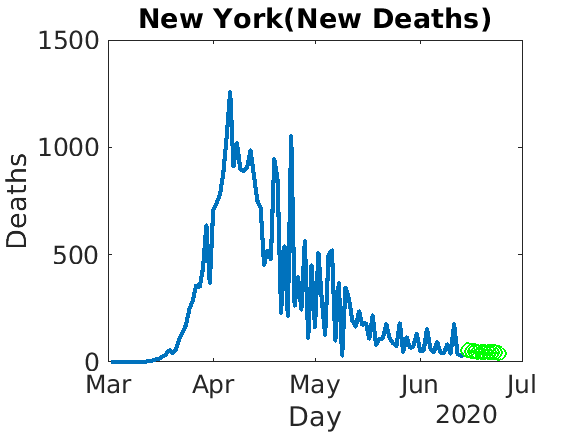

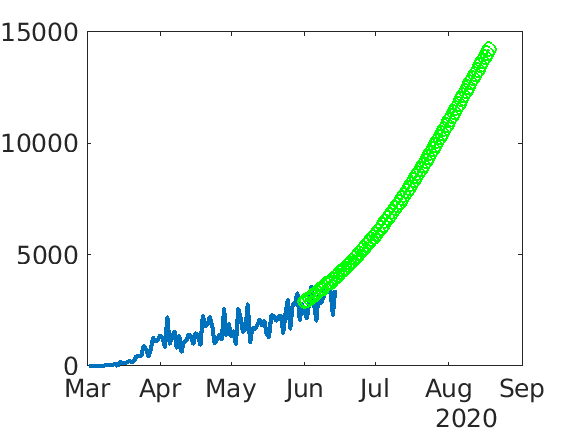

 

xx = find(strcmpi(countries, sel_reg));
if isempty(xx)
    cid = 1; % Default to the first region in the list
else
    cid = xx;
end

eval(['deaths_un = deaths_un_' num2str(un) '(:, 1:sel_horizon);']);
eval(['deaths_released_un = deaths_released_un_' num2str(un) '(:, 1:sel_horizon);']);

offset = 40;
trueshow = (offset:size(deaths, 2));
Tx = datetime(2020, 1, 21)+ caldays(trueshow);
plot(Tx(2:end), diff(deaths(cid, trueshow)), 'LineWidth', 3);
hold on;

Tx = datetime(2020, 1, 21)+caldays((T_full:T_full+sel_horizon-1));
yy = deaths_un(cid, :);
yy = diff(yy); Tx = Tx(2:end);
plot(Tx, yy, 'g', 'Marker', 'o', 'LineWidth', 2, 'MarkerSize', 10); hold off;
title([countries{cid} '(New Deaths)'])
xlabel('Day');
ylabel('Deaths');